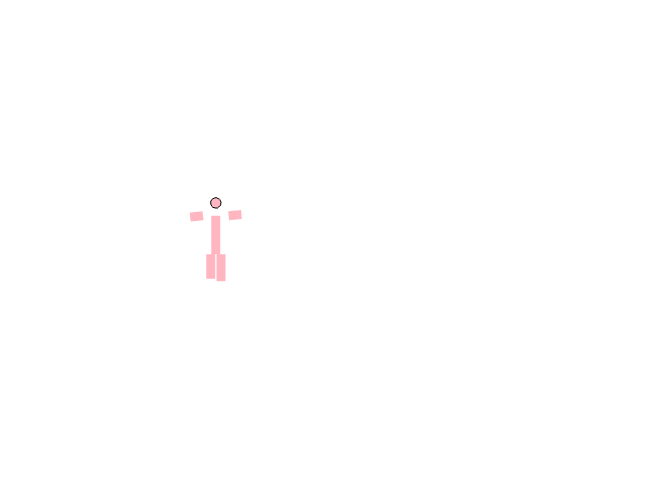

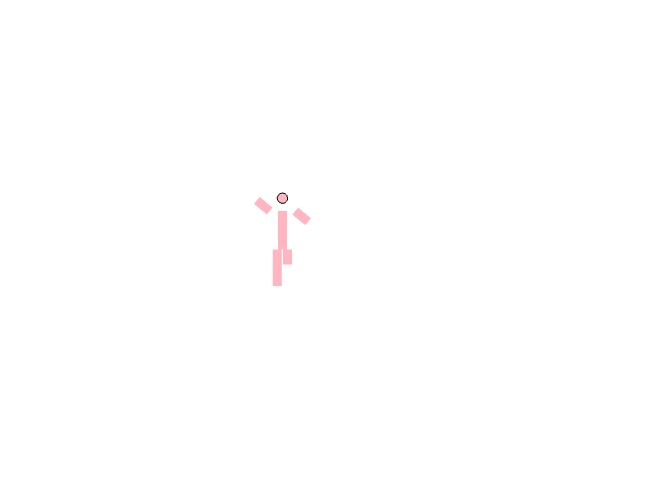

figure;
axis([-5 15 0 10]);
axis equal;
axis off;

x = 0;
y = 5;

%create the body here:
head = [0, 1];
body = [0, 0.5; 0, -1];
left_leg = [-0.2, -1; -0.2, -2];
right_leg = [0.2, -1; 0.2, -2];
left_arm = [-0.5, 0.5; -1, 0];
right_arm = [0.5, 0.5; 1, 0];

for k = 1:300
    cla;
    
    x = x + 0.05;
    
    theta = 0.5 * sin(0.1 * k);

    %moving body
    left_leg(2, 2) = -2 + 0.5 * sin(0.1 * k);
    right_leg(2, 2) = -2 - 0.5 * sin(0.1 * k);
    left_arm(2, 2) = 0.5 - 0.5 * sin(0.1 * k);
    right_arm(2, 2) = 0.5 + 0.5 * sin(0.1 * k);
    
    rectangle('Position', [x+head(1)-0.2, y+head(2)-0.2, 0.4, 0.4], 'Curvature', [1, 1], 'FaceColor', '#FFB6C1');
    
    %showing body
    line(x+body(:,1), y+body(:,2), 'LineWidth', 5, 'Color', '#FFB6C1');
    line(x+left_leg(:,1), y+left_leg(:,2), 'LineWidth', 5, 'Color', '#FFB6C1');
    line(x+right_leg(:,1), y+right_leg(:,2), 'LineWidth', 5, 'Color', '#FFB6C1');
    line(x+left_arm(:,1), y+left_arm(:,2), 'LineWidth', 5, 'Color', '#FFB6C1');
    line(x+right_arm(:,1), y+right_arm(:,2), 'LineWidth', 5, 'Color', '#FFB6C1');

    pause(0.05);
end